Testing file: task2_3.mat


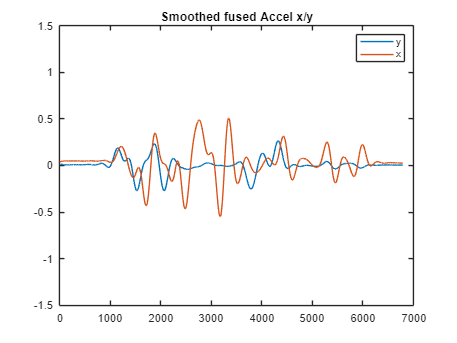

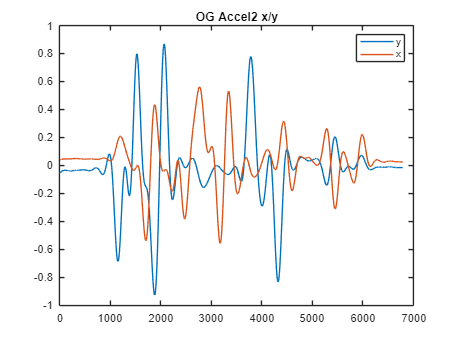

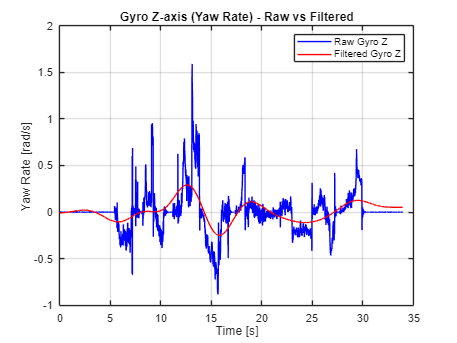

    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    0.1000         0         0
         0         0         0    0.1000         0
         0         0         0         0         0

Step 50:z_pred:    1.1759
    1.9131
    1.2320

z_meas:    1.1620
    1.9130
    1.2180

Printing K:   -0.4973    0.0000    0.4973
    0.0055   -0.9966    0.0055
   -0.0123    0.0000    0.0123
    0.0001   -0.0246    0.0001
    0.0000    0.0000   -0.0000

Step 100:z_pred:    1.1730
    1.9061
    1.2352

z_meas:    1.1630
    1.9060
    1.2250

Printing K:   -0.4970    0.0000    0.4970
    0.0055   -0.9964    0.0055
   -0.0245    0.0000    0.0245
    0.0003   -0.0492    0.0003
    0.0000   -0.0000   -0.0000

Step 150:z_pred:    1.1740
    1.9131
    1.2344

z_meas:    1.1600
    1.9130
    1.2200

Printing K:   -0.4968    0.0000    0.4968
    0.0055   -0.9965    0.0055
   -0.0364    0.0000    0.0364
    0.0004   -0.0731    0.0004
   

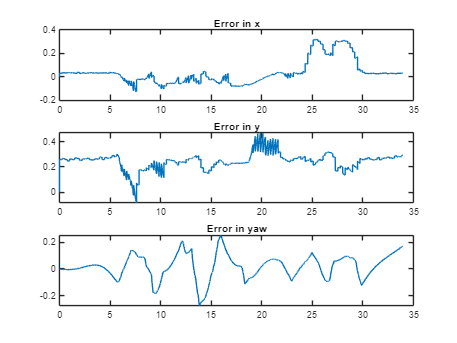

Absolute RMSE for task2_3.mat: 0.1101 m


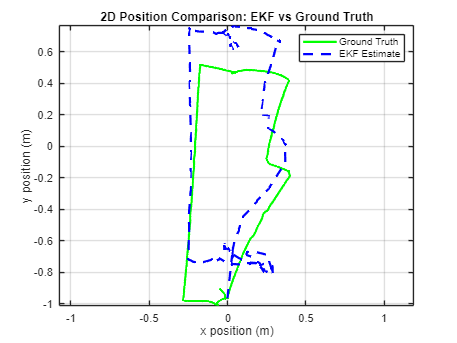

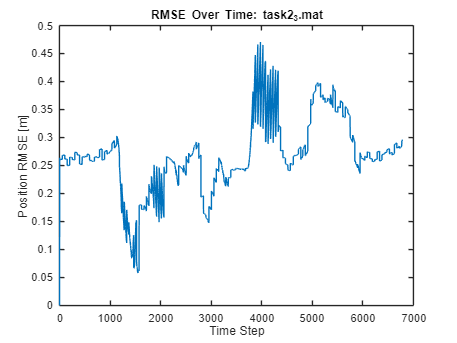

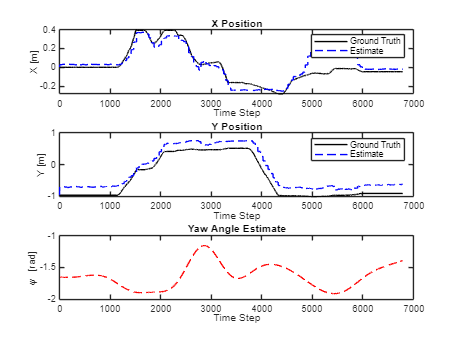

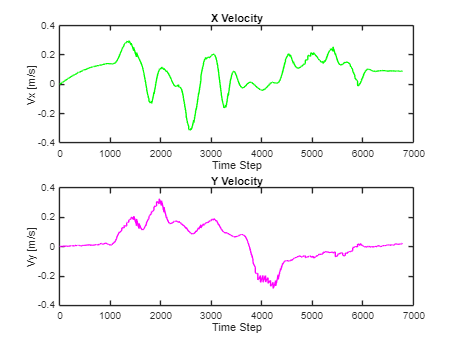

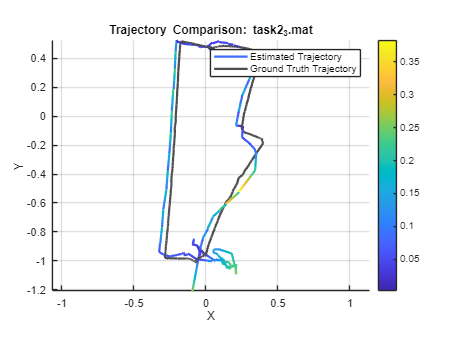

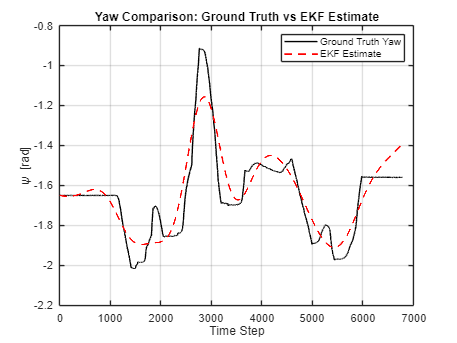

clear;clc; %Eval Script
taskFiles = { %'calib2_straight.mat'
    'task2_1.mat'%, 'task1_2.mat', 'task1_3.mat', 'task1_4.mat', ...
    %'task2_1.mat', 'task2_2.mat', 'task2_3.mat', 'task2_4.mat'
};

sensor_calibration_data = load('sensor_calibration.mat');


for k = 1:length(taskFiles)
    fprintf('\n==============================\n');
    fprintf('Testing file: %s\n', taskFiles{k});
    fprintf('==============================\n');

    try
        % Load the task file
        load(taskFiles{k}, 'out');


        % Call your EKF implementation
        warning('off', 'MATLAB:nearlySingularMatrix');  % disables that specific warning
        warning('on', 'all');                          % disables ALL warnings (if needed)


        [X_Est, P_Est, GT, gyro_z] = myEKF_nomag(out,diag([1, 1, 0.1, 0.1, 0.0]),1e14*diag([1,0.011,1]),1);



        % Convert ground truth to rigidtform3d
        pos = GT(:,1:3);
        N = size(pos,1);
        gtTforms(N) = rigidtform3d;
        for i = 1:N
            tGT = pos(i,:);
            RGT = eye(3);
            gtTforms(i) = rigidtform3d(RGT, tGT);
        end

        % Convert estimated states to rigidtform3d
        estTforms(N) = rigidtform3d;
        for i = 1:N
            tEst = [X_Est(i,1), X_Est(i,2), 0];
            R = eye(3);
            estTforms(i) = rigidtform3d(R, tEst);
        end

        % Compare trajectories
        metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'rigid');
        fprintf('Absolute RMSE for %s: %.4f m\n', taskFiles{k}, metrics.AbsoluteRMSE(2));
        % Extract x and y from the state estimate and ground truth
        x_est = X_Est(:,1);
        y_est = X_Est(:,2);
 
        x_gt = GT(:,1);
        y_gt = GT(:,2);
        
        % Plotting
        figure;
        plot(x_gt, y_gt, 'g-', 'LineWidth', 2); hold on;
        plot(x_est, y_est, 'b--', 'LineWidth', 2);
        legend('Ground Truth', 'EKF Estimate');
        xlabel('x position (m)');
        ylabel('y position (m)');
        title('2D Position Comparison: EKF vs Ground Truth');
        axis equal;
        grid on;


        % RMSE over time
        positionErrors = sqrt(sum((X_Est(:,1:2) - GT(:,1:2)).^2, 2));
        figure;
        plot(1:N, positionErrors);
        title(['RMSE Over Time: ', taskFiles{k}]);
        xlabel('Time Step'); ylabel('Position RMSE [m]');

        % Visualisation of all states
        figure;
        subplot(3,1,1);
        plot(1:N, GT(:,1), 'k-', 1:N, X_Est(:,1), 'b--');
        title('X Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('X [m]');

        subplot(3,1,2);
        plot(1:N, GT(:,2), 'k-', 1:N, X_Est(:,2), 'b--');
        title('Y Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('Y [m]');

        subplot(3,1,3);
        plot(1:N, X_Est(:,5), 'r--');
        title('Yaw Angle Estimate'); xlabel('Time Step'); ylabel('\psi [rad]');

        % Velocity visualisation
        figure;
        subplot(2,1,1);
        plot(1:N, X_Est(:,3), 'g'); title('X Velocity'); xlabel('Time Step'); ylabel('Vx [m/s]');
        subplot(2,1,2);
        plot(1:N, X_Est(:,4), 'm'); title('Y Velocity'); xlabel('Time Step'); ylabel('Vy [m/s]');


        figure;
        plot(metrics, 'absolute-translation');
        title(['Trajectory Comparison: ', taskFiles{k}]);
        view(0,90)
        rotate3d on;

        figure;
        plot(1:N,(GT(:,4)), 'k-')
        hold on
        plot(1:N, (X_Est(:,5)), 'r--', 'LineWidth', 1.5);
        hold off
        legend('Ground Truth Yaw', 'EKF Estimate');
        xlabel('Time Step');
        ylabel('\psi [rad]');
        title('Yaw Comparison: Ground Truth vs EKF Estimate');
        grid on;

    catch ME
        warning('Failed to process %s: %s', taskFiles{k}, ME.message);
    end
end

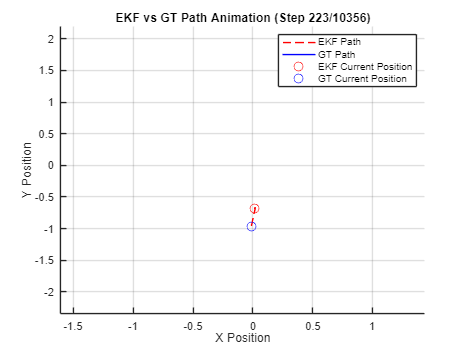

animate_paths(X_Est,GT,0.01)



function animate_paths(X_Est, GT, pause_time)
    % ANIMATE_PATHS Animates the EKF estimated path and the ground truth path from start to finish.
    %
    % Parameters:
    %   X_Est      - Matrix of EKF estimated states (N x M), where M >= 2, with the first two columns as x and y positions.
    %   GT         - Matrix of ground truth states (N x P), where P >= 2, with the first two columns as x and y positions.
    %   pause_time - Time (in seconds) to pause between each frame of the animation (default: 0.1).
    %
    % Example:
    %   animate_paths(X_Est, GT, 0.1);

    % Set default pause time if not provided
    if nargin < 3
        pause_time = 0.1;
    end

    % Get the number of time steps
    num_steps = min(size(X_Est, 1), size(GT, 1));

    % Extract position data
    ekf_path = X_Est(:, 1:2); % First two columns are x and y positions
    gt_path = GT(:, 1:2);     % First two columns are x and y positions

    % Create a new figure
    figure;
    hold on;

    % Set axis limits based on the full paths
    all_x = [ekf_path(:,1); gt_path(:,1)];
    all_y = [ekf_path(:,2); gt_path(:,2)];
    xlim([min(all_x)-1, max(all_x)+1]);
    ylim([min(all_y)-1, max(all_y)+1]);

    % Add labels and title
    xlabel('X Position');
    ylabel('Y Position');
    title('EKF vs GT Path Animation');
    grid on;

    % Initialize plot objects for EKF and GT paths
    ekf_line = plot(nan, nan, 'r--', 'DisplayName', 'EKF Path'); % Red dashed line
    gt_line = plot(nan, nan, 'b-', 'DisplayName', 'GT Path');    % Blue solid line

    % Initialize plot objects for current positions (markers)
    ekf_marker = plot(nan, nan, 'ro', 'MarkerSize', 8, 'DisplayName', 'EKF Current Position'); % Red circle
    gt_marker = plot(nan, nan, 'bo', 'MarkerSize', 8, 'DisplayName', 'GT Current Position');   % Blue circle

    % Add legend
    legend;

    % Animate the paths
    for t = 1:num_steps
        % Update the EKF path
        set(ekf_line, 'XData', ekf_path(1:t, 1), 'YData', ekf_path(1:t, 2));
        % Update the GT path
        set(gt_line, 'XData', gt_path(1:t, 1), 'YData', gt_path(1:t, 2));

        % Update the current position markers
        set(ekf_marker, 'XData', ekf_path(t, 1), 'YData', ekf_path(t, 2));
        set(gt_marker, 'XData', gt_path(t, 1), 'YData', gt_path(t, 2));

        % Update the title to show the current time step
        title(sprintf('EKF vs GT Path Animation (Step %d/%d)', t, num_steps));

        % Force MATLAB to draw the updated plot
        drawnow;

        % Pause to control animation speed
        pause(pause_time);
    end

    % Keep the final plot on screen
    hold off;
end

